clc,clear,close all

% f: 函数
f = @(x) 1./(1+25*x.^2);

% x_train: 插值点
x_train = -1:0.2:1;     %注意，这里 x_train 应该输入一个行向量

% y_train: 插值点处的函数值
y_train = f(x_train);

% x: 要预测的点
x= -1:0.01:1;

% y: 预测的函数值
y = myfun(x_train,y_train,x);

% y_real: 真实的函数值
y_real = f(x);

% interpolation_error: 误差. F 范数
interpolation_error = norm(y_real-y);

% 输出结果
disp('插值拟合结果为')
disp(y)
disp('真实值为')
disp(y_real)
disp('误差为')

误差为


disp(interpolation_error)

    8.2077



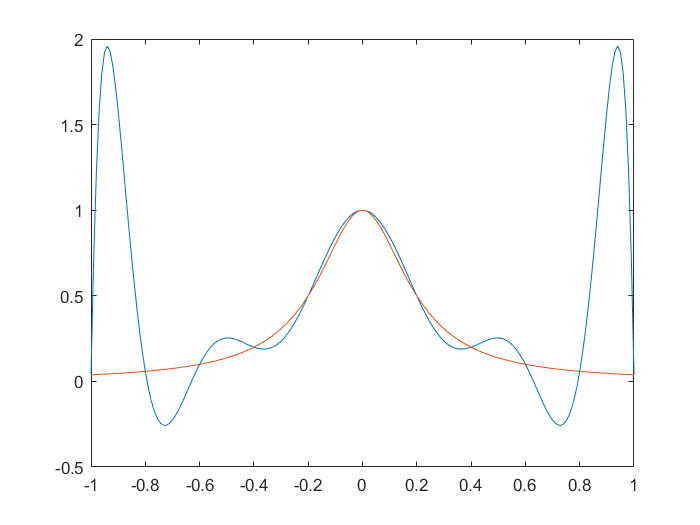

plot(x,y)
hold on
plot(x,y_real)